# **Lab 9**

### **Objective:**

The objective of this lab is to create a practical understanding of the Continuous time Fourier Series (Chapter 3 of textbook) and to prove various properties of the CTFS.

### **Theoretical Background:**

The Continuous Time Fourier Series is used for representation of continuous-time periodic signals:

CTFS representation of a periodic signal:        

Fourier Series Coefficients of a periodic signal:

### **Properties of the Continuous Time Fourier Series:**

There are many properties associated with the CTFS, in this lab the students will prove the following two properties, where:

- x(t) and y(t) are two continuous time periodic signals with period T and fundamental frequency and are the Fourier Series Coefficients.

#### **Multiplication:**

- The Fourier Series representation of the product of two continuous time periodic signals x(t) and y(t) is equal to the convolution of their Fourier Series coefficients

#### **Differentiation:**

- The Fourier Series representation of differentiation of a periodic signal x(t) is equal to –jw*(Fourier Series of x(t)).

### **Tasks:**

The following tasks are to be performed **individually** by each student:

#### **Task 1:**

Create separate functions in MATLAB for Continuous Time Fourier Series (CTFS), i.e. Fourier series coefficients of a signal and the Inverse Continuous Time Fourier Series (ICTFS), i.e. creating signal from Fourier Series Coefficients.

#### **Task 2:**

Using the functions for CTFS and ICTFS created in Task 1, prove the following properties (explained in theoretical background) of CTFS:

- Multiplication Property

- Differentiation Property

The specifications of the two signals should be:

- x(t) =  

- y(t) =  

- The signal period Tp=2*pi

- Number of coefficients k= -10 to 10

### Task 1 

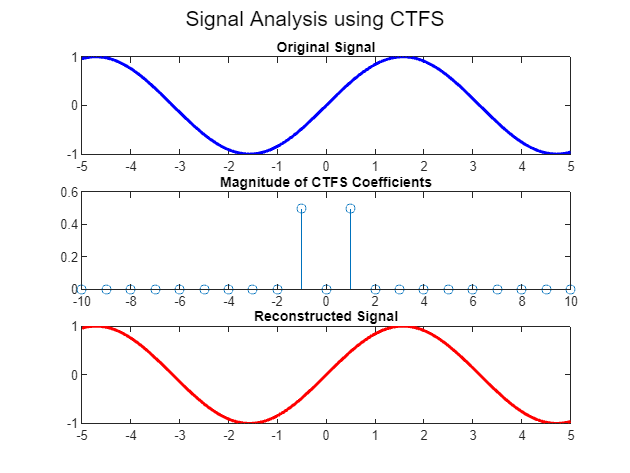

syms t ak;

T = 2*pi;
w = (2*pi)/T;
x = sin(t);
ak = CTFS(x, T);
x1 = ICTFS(ak, T);

figure;
subplot(3,1,1);
fplot(x, 'blue', 'linewidth', 2);
title('Original Signal');

subplot(3,1,2);
stem(-10:10, abs(ak));
title('Magnitude of CTFS Coefficients');

subplot(3,1,3);
fplot(x1, 'r', 'linewidth', 2);
title('Reconstructed Signal');

sgtitle('Signal Analysis using CTFS');

### Task 2 

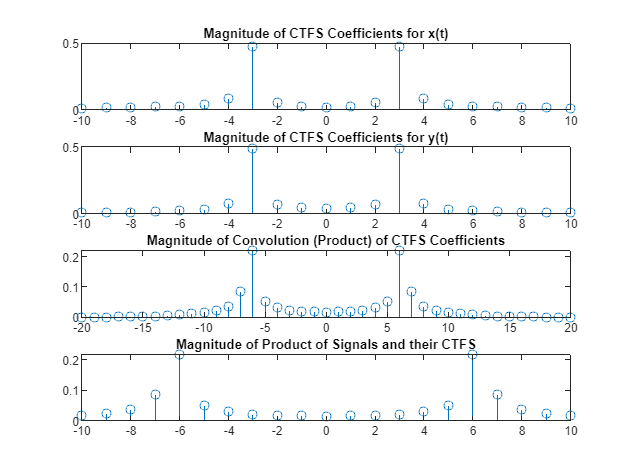

% Task 2
syms t;

% Signal specifications
Tp = 2*pi;
k_values = -10:10;

% Define signals x(t) and y(t)
x = sin(pi*t);
y = cos(pi*t);

% Calculate CTFS coefficients for x(t) and y(t)
ak_x = CTFS(x, Tp);
ak_y = CTFS(y, Tp);

% Multiplication Property: Convolution of CTFS coefficients
ak_product = conv(ak_x, ak_y);

product = x * y;

% Reconstruct the product signal using the convolution result
x_y_product = CTFS(product, Tp);

% Differentiation Property: -jw * CTFS coefficients
Dif_x = diff(x, t);
ak_diff_x = CTFS(Dif_x, Tp);
ak_diff_x_property = -1i * k_values * (2*pi/Tp) .* ak_x;

% Plotting results
figure;

subplot(4,1,1);
stem(k_values, abs(ak_x));
title('Magnitude of CTFS Coefficients for x(t)');

subplot(4,1,2);
stem(k_values, abs(ak_y));
title('Magnitude of CTFS Coefficients for y(t)');

subplot(4,1,3);
stem(-20:20, abs(ak_product));
title('Magnitude of Convolution (Product) of CTFS Coefficients');
subplot(4,1,4)
stem(-10:10,abs(x_y_product));
title('Magnitude of Product of Signals and their CTFS');

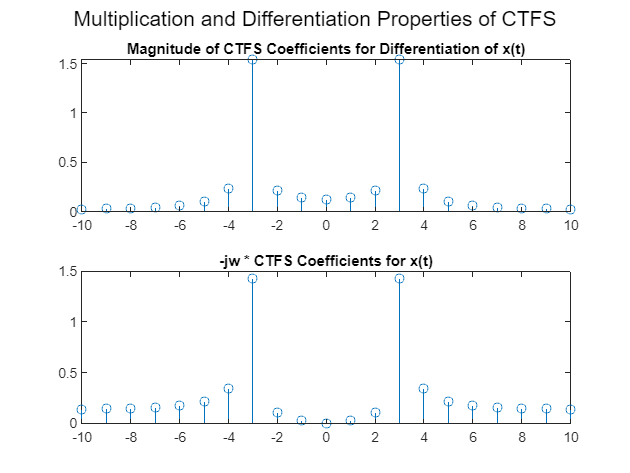

figure;

subplot(2,1,1);
stem(k_values, abs(ak_diff_x));
title('Magnitude of CTFS Coefficients for Differentiation of x(t)');

subplot(2,1,2);
stem(k_values, abs(ak_diff_x_property));
title('-jw * CTFS Coefficients for x(t)');

sgtitle('Multiplication and Differentiation Properties of CTFS');

#### Function 1 

function ak = CTFS(x, T)
    syms t;
    w = (2*pi)/T;
    
    ak = zeros(1, 21);  % Initializing ak to zeros
    
    for k = -10:10
        ak(k+11) = (1/T) * int(x * exp(-1i*k*w*t), t, 0, T);
    end
end

#### Function 2 

function x = ICTFS(ak, T)
    syms t;
    w = (2*pi)/T;

    x = 0;
    for k = -10:10
        x = x + ak(k+11) * exp(1j*k*w*t);
    end
end